# Problemario 4 espectroscopía

## Ejercicio 21

clc; clear all;
format long
 x = [1 2 3 4];
y = [0.230 0.436 0.638 0.848];
p = polyfit(x,y,1);
f = polyval(p,x);
m=p(1)

m =    0.205600000000000


b=p(2)

b =    0.024000000000000


[r2 rmse] = rsquare(y,f);
plot(x,y,'b*');
hold on; 
plot(x,f,'k-','LineWidth',1);
xlim([0 x(end)+0.5])
grid on
grid minor
title(strcat(['$R^2$ = ' num2str(r2) '\qquad\qquad\qquad\qquad RMSE = ' num2str(rmse)]), 'interpreter', 'latex'); 
xlabel('Concentracion (ppm\, P)', 'interpreter', 'latex')
ylabel('Absorbancia (650 nm)', 'interpreter', 'latex')
% Datos experimentales
 nb=[0.518]; % datos obtenidos
 xb=(nb-p(2))./p(1) % cálculo de y

xb =    2.402723735408561


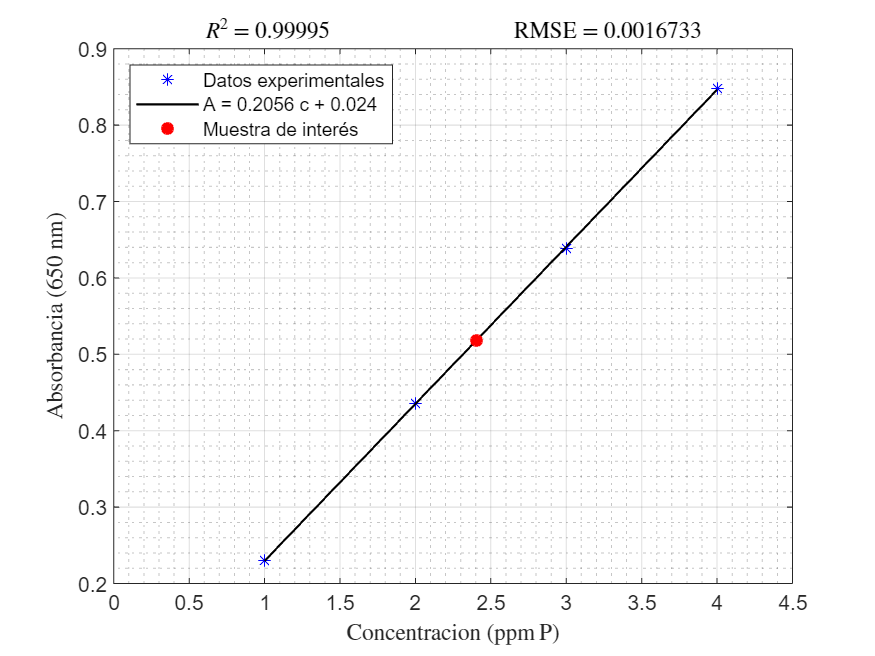

 plot(xb,nb,'r*','LineWidth',2)
 legend("Datos experimentales",['A = ' num2str(m) ' c + ' num2str(b)],"Muestra de interés",'Location','northwest')
 hold off

## Ejercicio 23

clc; clear all;
format long
 x = [2 6 10 14 18];
y = [0.065 0.205 0.338 0.474 0.598];
p = polyfit(x,y,1);
f = polyval(p,x);
m=p(1)

m =    0.033375000000000


b=p(2)

b =    0.002250000000000


[r2 rmse] = rsquare(y,f);
plot(x,y,'b*');
hold on; 
plot(x,f,'k-','LineWidth',1);
xlim([0 x(end)+1])
grid on
grid minor
title(strcat(['$R^2$ = ' num2str(r2) '\qquad\qquad\qquad\qquad RMSE = ' num2str(rmse)]), 'interpreter', 'latex'); 
xlabel('Concentracion ($\mu$M)', 'interpreter', 'latex')
ylabel('Absorbancia (550 nm)', 'interpreter', 'latex')
% Datos experimentales
 nb=[0.402]; % datos obtenidos
 xb=(nb-p(2))./p(1) % cálculo de y

xb =   11.977528089887638


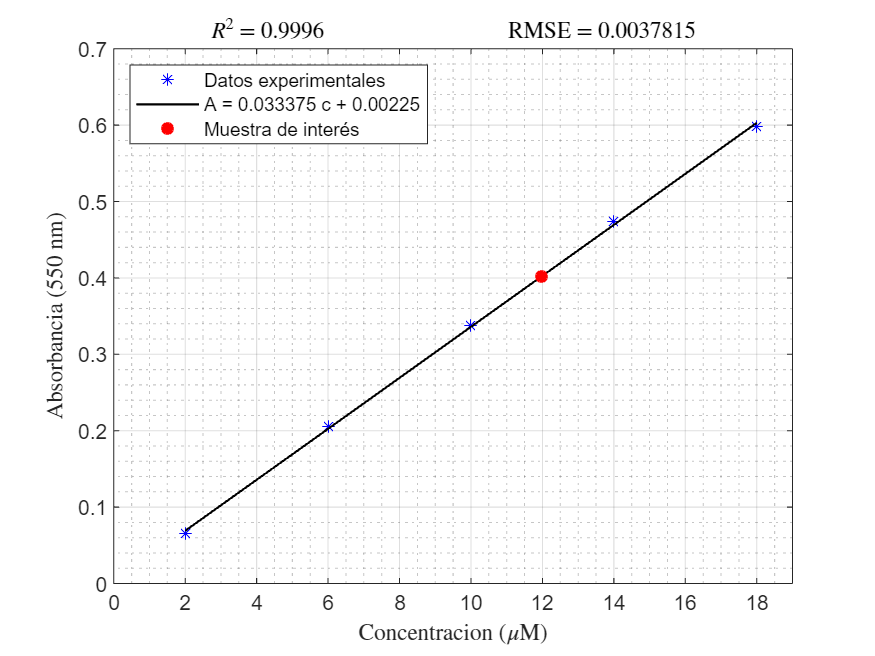

 plot(xb,nb,'r*','LineWidth',2)
 legend("Datos experimentales",['A = ' num2str(m) ' c + ' num2str(b)],"Muestra de interés",'Location','northwest')
 hold off